h_bar = 6.582e-16;
a = 5.6532e-10;

## **1)**

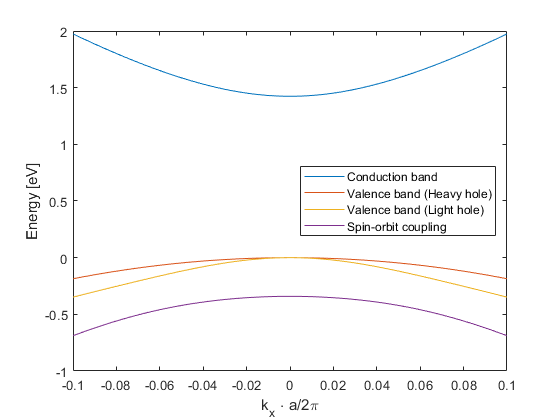

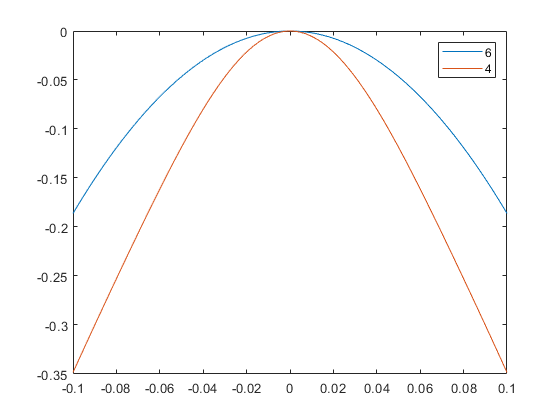

conduction_coeff =   -18.6141   -0.0000    0.0000


d2 = -3.0137e-19

m = -1.4375e-12

% Plot the resulting band structure
k_x_min = -0.1*2*pi/a;
k_x_max = 0.1*2*pi/a;
n_points = 100;
k_x_mesh = linspace(k_x_min, k_x_max, n_points)*a/(2*pi);

bands = band_structure(k_x_min, k_x_max, n_points);
plot(k_x_mesh, bands(:, 8:-2:1))
%plot(k_x_mesh, 1:100)
xlabel('k_x \cdot a/2\pi');
ylabel('Energy [eV]');
%xlim([k_x_min, k_x_max]);
legend('Conduction band', 'Valence band (Heavy hole)', 'Valence band (Light hole)', 'Spin-orbit coupling', 'Location', 'east');